clc; clearvars; close all
trainTable = readtable("DailyDelhiClimateTrain.csv");
testTable = readtable("DailyDelhiClimateTest.csv");

trainMat = table2array(trainTable(:, 2:end));
testMat = table2array(testTable(:, 2:end));

dataTable = [trainTable; testTable];

idx = ismissing(dataTable);
idx(idx~=0)


ans =

  0×1 empty logical array



% check for duplicate dates
[~, idx] = unique(table2array(dataTable(:, 1)), 'stable');
duplicate_idx = setdiff(1:numel(table2array(dataTable(:, 1))), idx)

duplicate_idx = 1463

% remove the more unusual observation of the duplicates
dataTable(duplicate_idx - 1,:) = [];

% check if all dates between the first and the last are included
days(table2array(dataTable(end, 1))-table2array(dataTable(1, 1))) + 1

ans = 1575

size(dataTable, 1)

ans = 1575


% are datetimes evenly spaced
unique(caldiff(table2array(dataTable(:, 1))))

ans = calendarDuration
   1d


x = table2array(dataTable(:, "meanpressure"));
idxLarge = x > 1050;
idxSmall = x < 950;
x(idxLarge) = NaN;
x(idxSmall) = NaN;
idx = isnan(x);
x(idx) = mean(x, "omitmissing");
dataTable{:, "meanpressure"} = x;

dataMat = table2array(dataTable(:, 2:end));

varNames = dataTable.Properties.VariableNames;

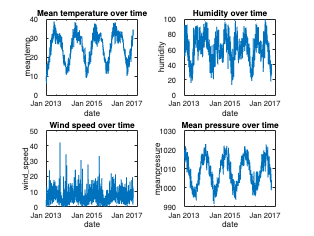

figure
subplot(2, 2, 1)
plot(dataTable, "date", "meantemp")
title("Mean temperature over time")

subplot(2, 2, 2)
plot(dataTable, "date", "humidity")
title("Humidity over time")

subplot(2, 2, 3)
plot(dataTable, "date", "wind_speed")
title("Wind speed over time")

subplot(2, 2, 4)
plot(dataTable, "date", "meanpressure")
title("Mean pressure over time")

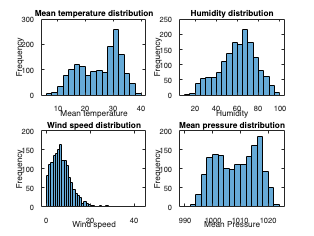

figure
subplot(2, 2, 1)
histogram(dataTable.meantemp)
xlabel("Mean temperature")
ylabel("Frequency")
title("Mean temperature distribution")

subplot(2, 2, 2)
histogram(dataTable.humidity)
xlabel("Humidity")
ylabel("Frequency")
title("Humidity distribution")

subplot(2, 2, 3)
histogram(dataTable.wind_speed)
xlabel("Wind speed")
ylabel("Frequency")
title("Wind speed distribution")

subplot(2, 2, 4)
histogram(dataTable.meanpressure)
xlabel("Mean Pressure")
ylabel("Frequency")
title("Mean pressure distribution")

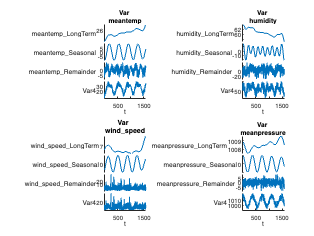

figure
for i = 1:size(dataMat, 2)
    D = trenddecomp(dataTable(:, i+1));
    D = addvars(D, dataMat(:, i));
    
    subplot(2, 2, i)
    stackedplot (D);
    xlabel("t");
    title(['Var ' strrep(varNames(i+1),'_','\_')])
end

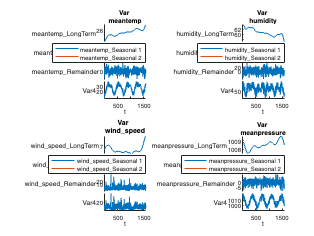

figure
for i = 1:size(dataMat, 2)
    D = trenddecomp(dataTable(:, i+1), "NumSeasonal", 2);
    D = addvars(D, dataMat(:, i));
    
    subplot(2, 2, i)
    stackedplot (D);
    xlabel("t");
    title(['Var ' strrep(varNames(i+1),'_','\_')])
end

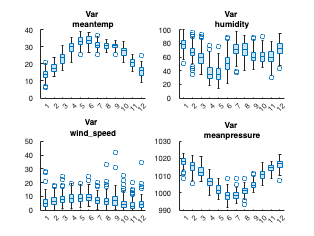

x = table2array(dataTable(:, 1));
x = x.Month

figure
for i = 1:size(dataMat, 2)
    subplot(2, 2, i)
    boxchart(x, dataMat(:, i))
    xlim([0.5 12.5])
    xticks(1:12)
    title(['Var ' strrep(varNames(i+1),'_','\_')])
end